# `antbounds_data` documentation

The `antbounds_data` function returns the coordinates of line data in the MEaSURES Antarctic Boundaries for IPY 2007-2009 from Satellite Radar dataset Version 2.

The Antarctic Boundaries dataset is described on the NSIDC site [here](http://nsidc.org/data/NSIDC-0709). An overview of the tools in this AMT plugin can be found [here](Antbounds_Contents.html).

## Syntax

## Description

`[lat,lon] = antbounds_data(datatype)` returns the geo coordinates (lat,lon) of any of the following datatypes: 

- `'coast'` seaward limit of the ice sheet

- `'gl'` landward limit of flexure detected by InSAR

- `'shelves'` a cell array of all ice 180 ice shelves in the dataset

- `'shelfname'` any of the shelf names in the dataset, must be exactly one of the following: 

`[x,y] = antbounds_data(datatype,'xy')` returns polar stereographic (true lat 71 S) coordinates in meters. 

`[...,names] = antbounds_data('shelves')` also returns an array of ice shelf names. 

## Example 1: Load and plot grounding lines and coastlines

Load and plot a continent's worth of coast line data. Plot the whole ice sheet as a blue patch object. 

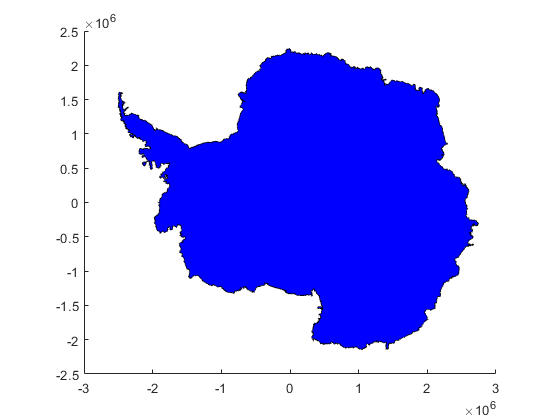

[lat,lon] = antbounds_data('coast'); 
patchps(lat,lon,'blue')

And overlaying a red grounding line is just as easy: 

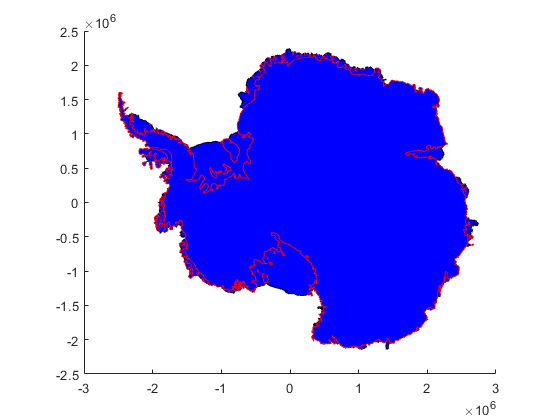

[gllat,gllon] = antbounds_data('gl'); 
plotps(gllat,gllon,'red')

## Example 2: Mask data corresponding to a specific ice shelf

Consider a 10 km resolution grid, 700 km wide, centered on Wilkins Ice Shelf. We can use [ `psgrid`](https://www.mathworks.com/matlabcentral/fileexchange/47638-antarctic-mapping-tools/content/AntarcticMappingTools/Documentation/html/psgrid_documentation.html) to create such a grid: 

[xgrid,ygrid] = psgrid('wilkins ice shelf',700,10,'xy');

That grid looks like this: 

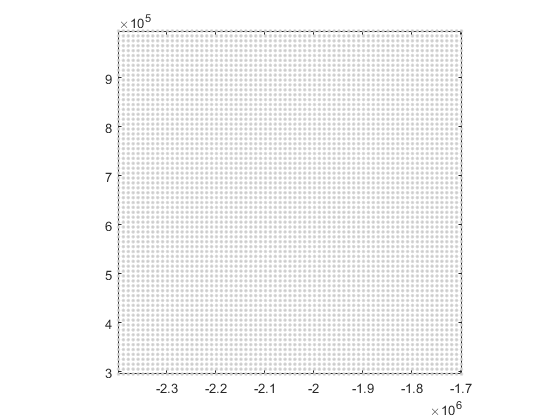

plot(xgrid,ygrid,'.','color',0.8*[1 1 1])
axis image
hold on

That doesn't tell us much, so let's put it into context of some grounding lines and coastlines. Make them all black: 

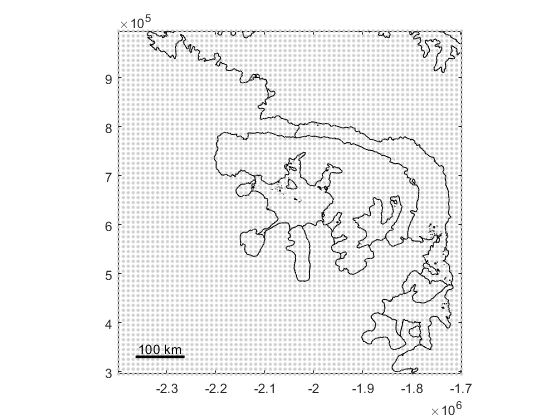

antbounds('gl','k') 
antbounds('coast','k') 
antbounds('shelves','k') 
scalebarps

If you want to find all your grid points that correspond to any ice shelf, the best tool for that is the [`isiceshelf`](isiceshelf.html) function. Let's identify ALL ice shelf grid points as black x marks: 

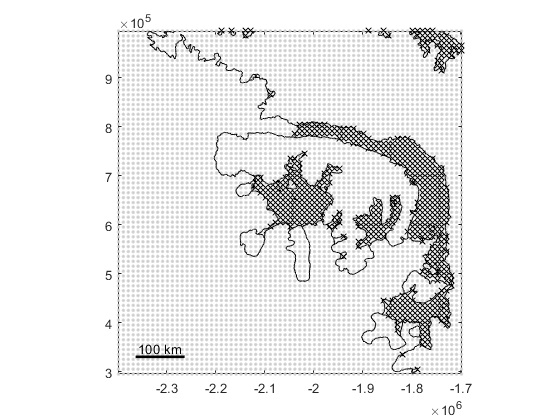

shelf = isiceshelf(xgrid,ygrid); 
plot(xgrid(shelf),ygrid(shelf),'kx')

But what if you're only interested in Wilkins Ice Shelf? The easiest way to determine which grid points are within the Wilkins Ice Shelf polygon is to load the outline of Wilkins Ice Shelf via `antbounds_data`, then use the Matlab function  `inpolygon` to determine which points are inside the Wilkins outline. Start by loading the polygon and plot it as a thick red line: 

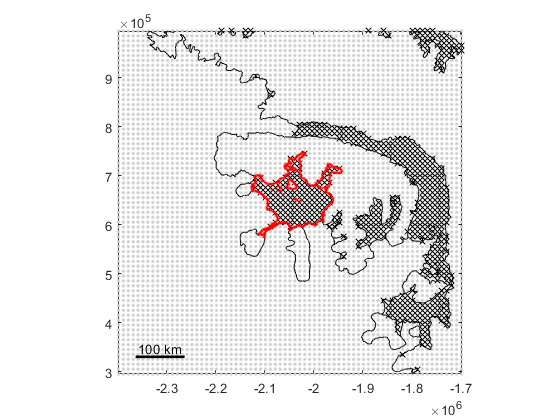

[wx,wy] = antbounds_data('wilkins','xy'); 
plot(wx,wy,'r','linewidth',2)

Now determine which grid points are inside the Wilkins outline and plot thos grid points as red circles: 

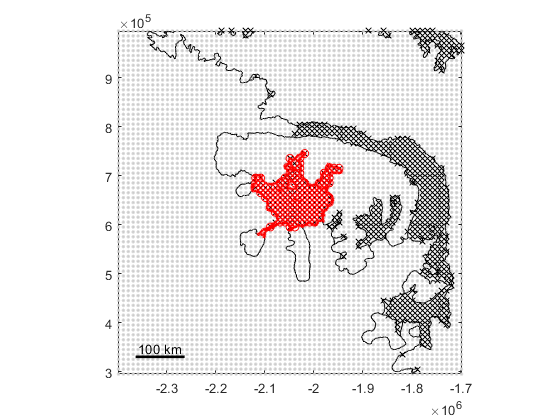

wilkins = inpolygon(xgrid,ygrid,wx,wy); 
plot(xgrid(wilkins),ygrid(wilkins),'ro')

Now label the ice shelves and use [ `mapzoomps`](https://www.mathworks.com/matlabcentral/fileexchange/47638-antarctic-mapping-tools/content/AntarcticMappingTools/Documentation/html/mapzoomps_documentation.html) to place an inset map in the upper right hand ('ne') corner. Below I'm using my [`rgb`](https://www.mathworks.com/matlabcentral/fileexchange/46872-intuitive-rgb-color-values-from-xkcd/content/XKCD_RGB/html/rgb_demo.html) function to automatically give the RGB values of dark blue

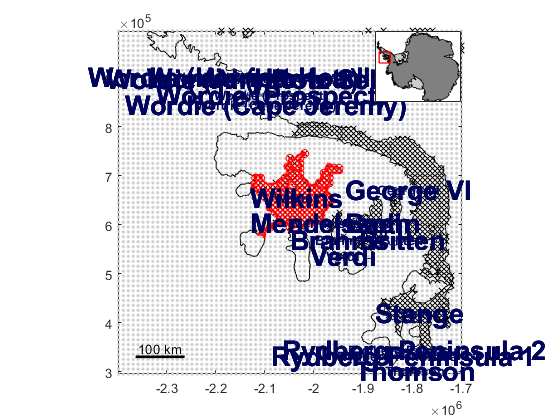

labelshelves('fontweight','bold','fontsize',20,'color',rgb('dark blue'))
mapzoomps('ne')

## Citing this dataset

If you use this dataset, please cite the following: 

- **The dataset:** Mouginot, J., B. Scheuchl, and E. Rignot. 2017. MEaSUREs Antarctic Boundaries for IPY 2007-2009 from Satellite Radar, Version 2. [Indicate subset used]. Boulder, Colorado USA. NASA National Snow and Ice Data Center Distributed Active Archive Center. [http://dx.doi.org/10.5067/AXE4121732AD](http://dx.doi.org/10.5067/AXE4121732AD). 

- **Literature citation:** Rignot, E., S. S. Jacobs, J. Mouginot, and B. Scheuchl. 2013. Ice-shelf melting around Antarctica, Science. 341. 266-270. [http://dx.doi.org/10.1126/science.1235798](http://dx.doi.org/10.1126/science.1235798). 

- **Antarctic Mapping Tools:** Greene, C. A., Gwyther, D. E., & Blankenship, D. D. Antarctic Mapping Tools for Matlab.  *Computers & Geosciences*. 104 (2017) pp.151-157. [doi:10.1016/j.cageo.2016.08.003](http://dx.doi.org/10.1016/j.cageo.2016.08.003).

## Author Info

This function and supporting documentation were written by [Chad A. Greene](http://www.chadagreene.com) of the University of Texas Institute for Geophysics (UTIG), November 2016. Updated May 2017. 